# PD2.2 Sensor Measurement Tutorial

**Making Music with MATLAB**

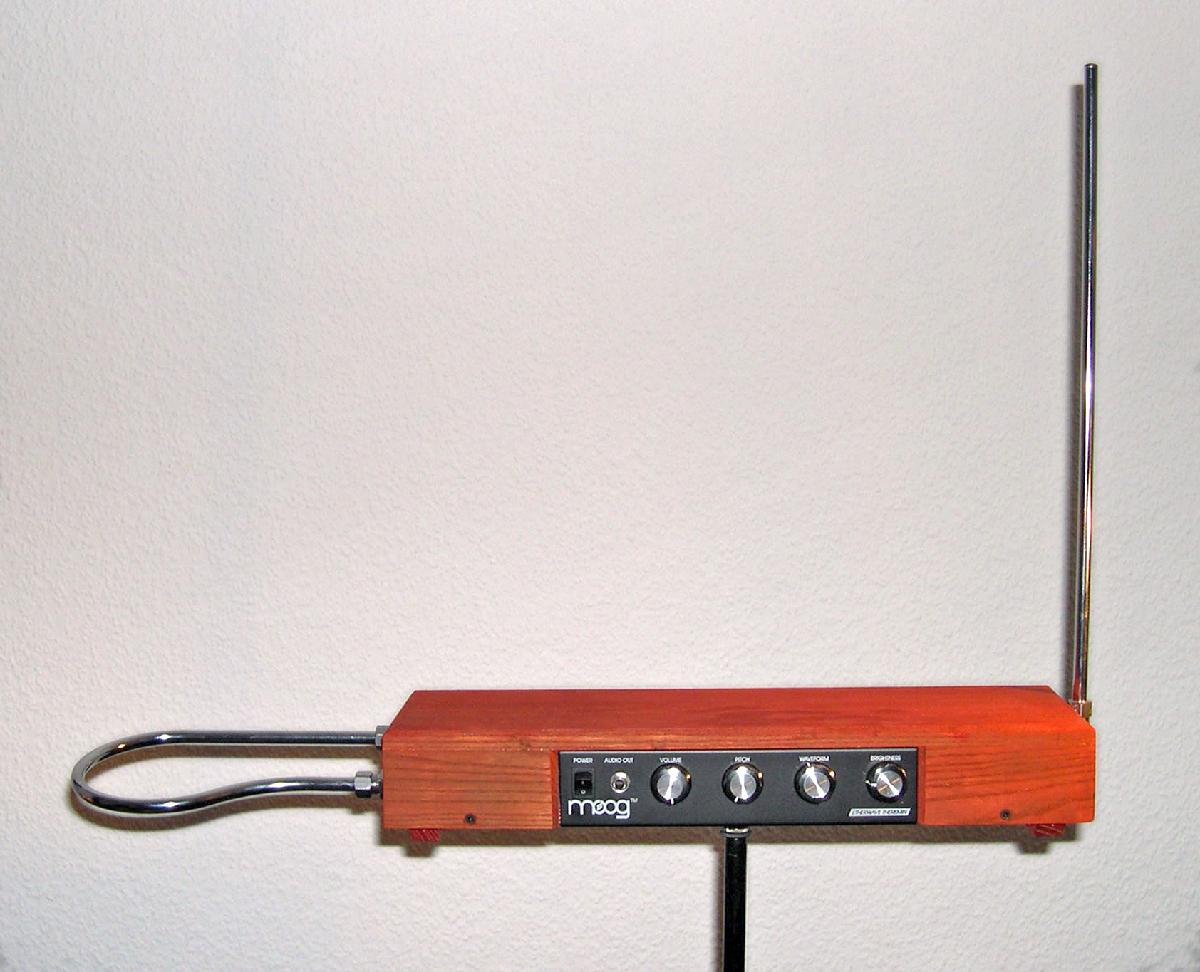

*Figure: An example of a theremin device*

Have you ever wanted to feel like you have superpowers by controlling various things in your daily life with just your mind (and your hands)? Well, now you can! Our design for this project is revolving all around the sound of music and the various things that arduinos and electronic sensors can help with. The inspiration for this idea came from a real life musical instrument known as a **theremin**, which is shown in the figure above. For all of the musical enthusiasts that Michigan Tech has, this is a good product for them, as it could perhaps be implemented in the band or used individually for aspiring artists looking to add a twist to their tunes. Music is not the only thing that this product could be used for, however, as you could easily use this as a warning system for various purposes around the world, such as a distance sensor for cars or a warning sensor for a factory machine. This is an extremely versatile unit as well, as you could easily add a light on it on top of the speaker to make sure that someone knows it is there.

This tutorial is going to show you how to set up and use our musically guided design.

The purpose of this circuit is to behave like the theremin shown above. A theremin is an electronic musical instrument controlled without physical contact by the performer. Theremins sense the relative position of the hands and control oscillators for frequency with one hand.

#### 1) Assemble the following Audio Alert circuit using your Arduino Kit. 

#### Note: Use the Passive Buzzer which does not have a sticker on its top.

****Make sure that the trigger and echo pins are assigned to their correct ports (D5 and D6 respectively); otherwise, it will not work.**

#### 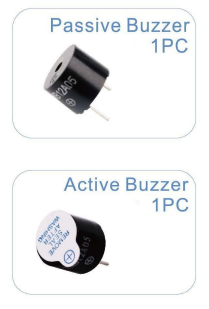

## 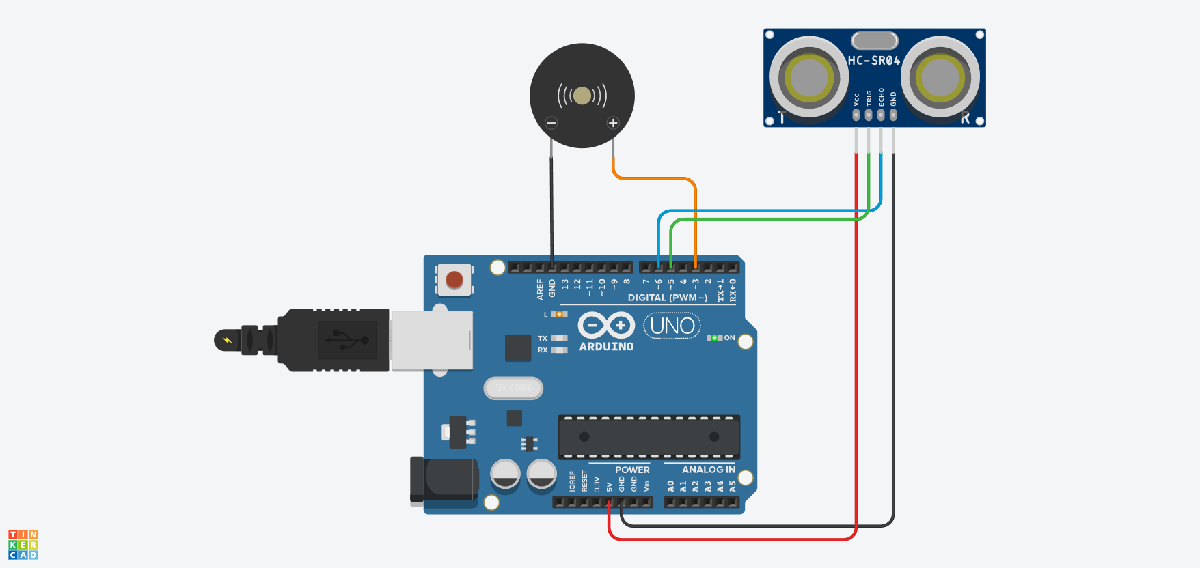

 *Figure: Theremin Sensor Drawing in TinkerCad*

This circuit uses an input of the ultrasonic sensor (HC-SR04) and an output of the passive buzzer that does not have the sticker on top. If you use the active buzzer, it might sound weird. To simplify this circuit, you can just connect the ultrasonic sensor and the speaker using the Female to Male wires located in your arduino kit.

**2) Run the follwing code and see what happens!**

After you start the program, move your hand vertically over the ultrasonic sensor. Try to keep your hand as flat as possible and move it up and down until you hear different frequencies being emitted. When moving your hand, try and move it as straight up as possible, otherwise you might hear some funky sounds. Otherwise, you can use a book or other flat object.

% PD2_2_Sensor_Measurement_Tutorial.mlx
% Date: 10/27/2024 

clear
clc
close all

% The circuit requires a passive buzzer on pin D3 and an ultrasonic sensor
% with trig on pin D5 and echo on pin D6

% Connect to Arduino and add library
hardwareTable = arduinolist;
arduino = arduino(hardwareTable{1, 1}, hardwareTable{1, 2}, 'Libraries', 'Ultrasonic');
ultrasonic = ultrasonic(arduino, 'D5', 'D6'); % Define to ultrasonic sensor
arduino.configurePin("D4", "Pullup")

% Variables
BUILT_IN_LED = "D13";
time = [];                  % Store time data
distance = [];           % Store distance data
note = ["C", "D", "E", "F", "G", "A", "B", "C5"]; % C major
%note = ["C", "D", "Eb", "E", "G", "A", "C5"]; % C major blues
%note = ["A", "B", "C5", "D#5", "E5", "F5", "G#5","A5"]; %A hungarian minor scale

range = .75;
line = animatedline(0, 0, "LineStyle", "none", "Marker", "*");

disp("Start") 

Start


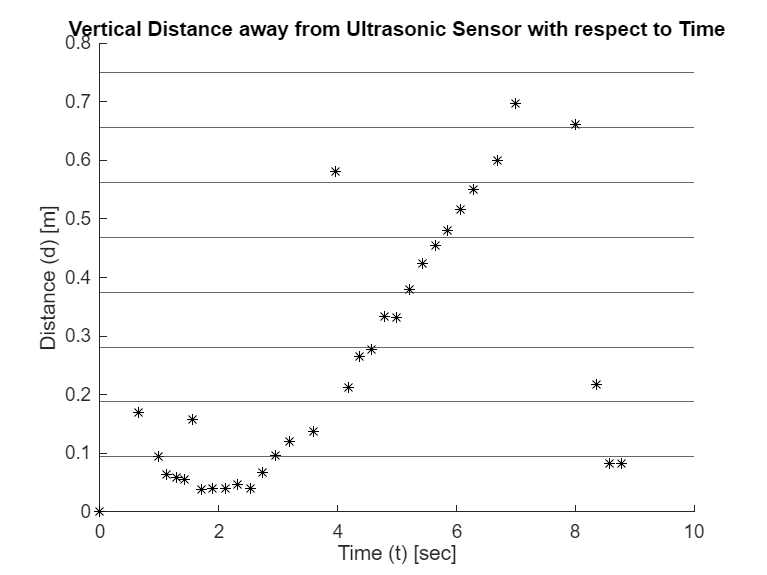

writeDigitalPin(arduino, BUILT_IN_LED, 0); % Turn off built in led to show code is running

tic(); % Start a timer for measuring

for i = 1:length(note)
    yline(((i*1.)/length(note))*range)
end
hold on

ylabel("Distance (d) [m]")
xlabel("Time (t) [sec]")
title("Vertical Distance away from Ultrasonic Sensor with respect to Time")

i = 1;
while (arduino.readDigitalPin("D4"))
    distance = readDistance(ultrasonic);

    if (distance < range)
        input = distance / range;
        playTone(arduino, 'D3', f(note(floor(input * length(note)) + 1)), .5);

        addpoints(line, toc(), distance);
        drawnow
        data(i) = distance; % Record data
        i = i + 1;
    end
end



fprintf("The average distance away from the sensor was: %f", mean(data))

Average: 0.253506



function frequency = f(s)
    % A function to give the frequency in Hz of a note from a string input
    % such as "A4" or "B#2" or "Eb5" if no octave is given, the function
    % will defualt to octave 4. This function will also accept vectors.
    % by Edison Bregger 10/22/2024

    % Set an easily changeable octave to defualt to if none is given 
    defualtOctave = 4;

    % Define size of final vector
    frequency = zeros(1, length(s), "double");

    % Loop through all strings
    for i = 1:length(s)

        % Get the string in all lower case at i
        input = convertStringsToChars(lower(s(i)));

        % Convert to note number
        switch input(1)
            case 'c'
                note = 1;
            case 'd'
                note = 3;
            case 'e'
                note = 5;
            case 'f'
                note = 6;
            case 'g'
                note = 8;
            case 'a'
                note = 10;
            case 'b'
                note = 12;
        end
    
        % Make sure an octave is specified
        if (length(input) > 1)

            % If a note is sharp or flat, modify the note number by 1
            % Also store the octave here because we know how long the array is
            if (input(2) == '#') % If sharp
                note = note + 1;
                if (length(input) > 2)
                    octave = str2double(input(3));
                else
                    octave = defualtOctave;
                end
            elseif (input(2) == 'b') % If flat
                note = note - 1;
                if (length(input) > 2)
                    octave = str2double(input(3));
                else
                    octave = defualtOctave;
                end
            else % If natural
                octave = str2double(input(2));
            end
        else
            octave = defualtOctave;
        end
    
        % n = notes away from A4
        n = note + (12 * octave) - 58; % A4 is 58 without the subtraction
        
        % Frequency can be found using n and this formula
        frequency(i) = 440 * 2^(n/12);
    end
end


Any Errors? (No Problem! Try These Steps)

- Is your Arudino Plugged in to the USB Port and LED lights are on?

- Head back and review the directions to figure out if anywhere overlooked.

- Check which pins your wires connect to, Also check that you have a good connection between wires. 

The desired effect is that when the distance sensor reads in different values, it will change notes played